# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'pdf';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING; %#ok<GVMIS> 
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp
. Processing the test case #1...


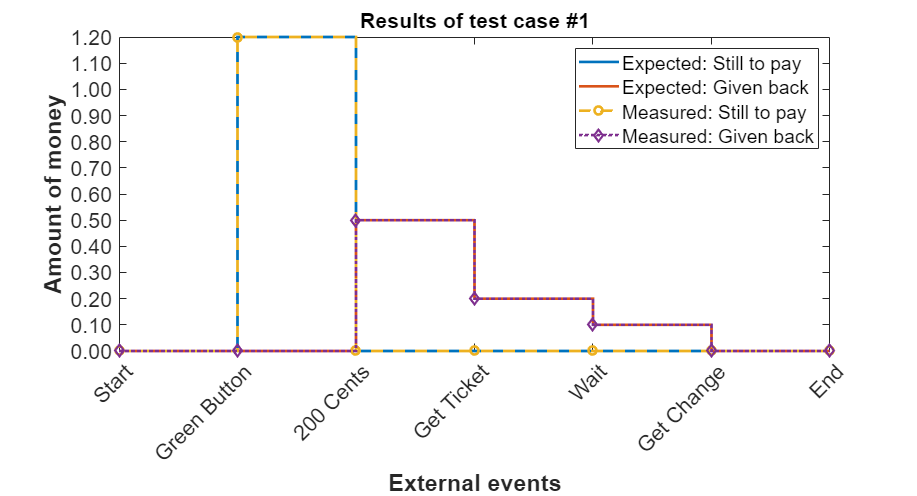


[Terse] Diagnostic logged (2022-07-01 17:28:02):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_784ea99f-352a-4aeb-8fd3-7ac68925e82a.fig
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_784ea99f-352a-4aeb-8fd3-7ac68925e82a.png
. Processing the test case #2...


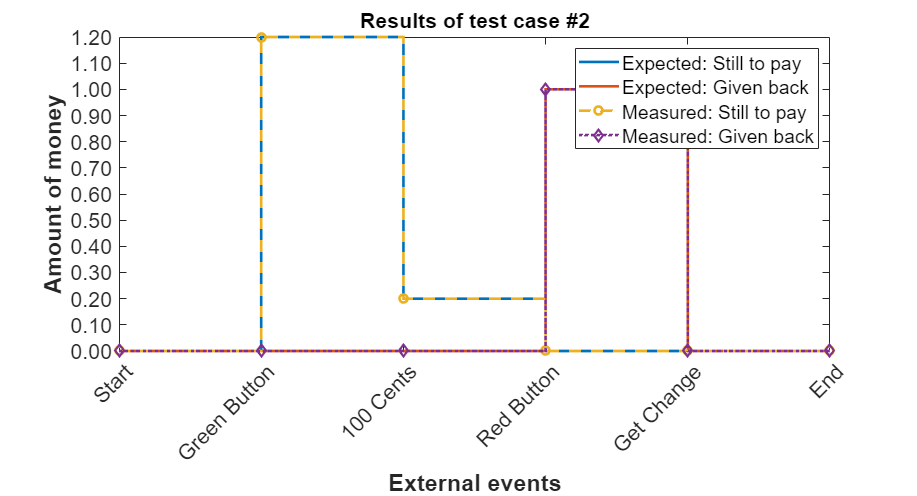


[Terse] Diagnostic logged (2022-07-01 17:28:19):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_6652f1be-192e-459b-b2ec-3776f60987e6.fig
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_6652f1be-192e-459b-b2ec-3776f60987e6.png
.. Processing the test case #3...


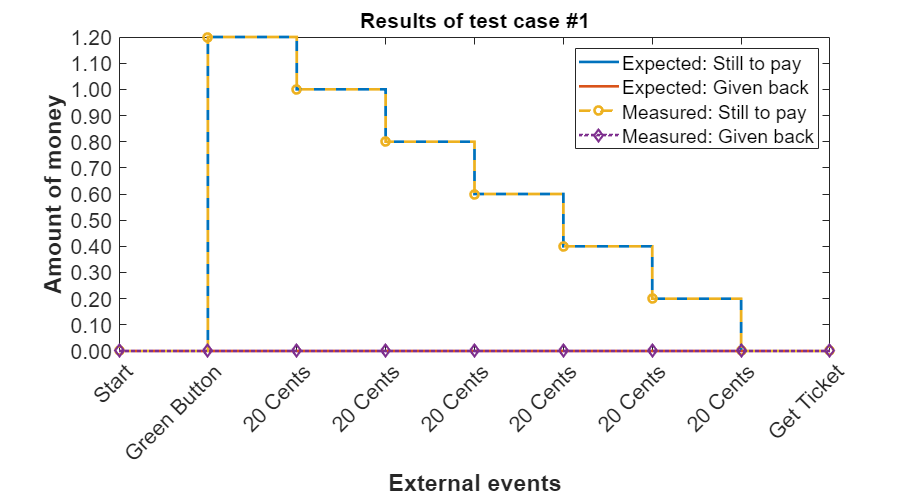


[Terse] Diagnostic logged (2022-07-01 17:28:55):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_b3fde601-0e91-48f5-840a-4d136af185ce.fig
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_b3fde601-0e91-48f5-840a-4d136af185ce.png
. Processing the test case #4...


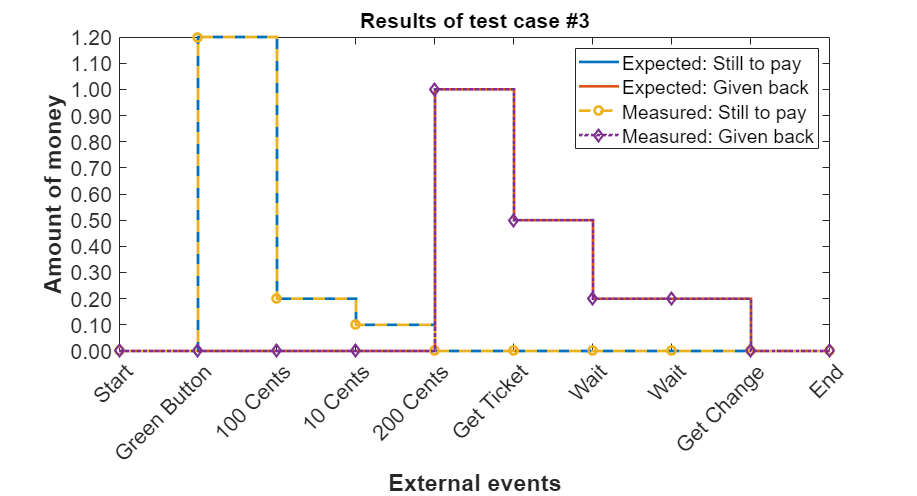


[Terse] Diagnostic logged (2022-07-01 17:29:16):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_c3872675-17a4-4cdb-8ed0-8847388a56f5.fig
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_c3872675-17a4-4cdb-8ed0-8847388a56f5.png
. Processing the test case #4...


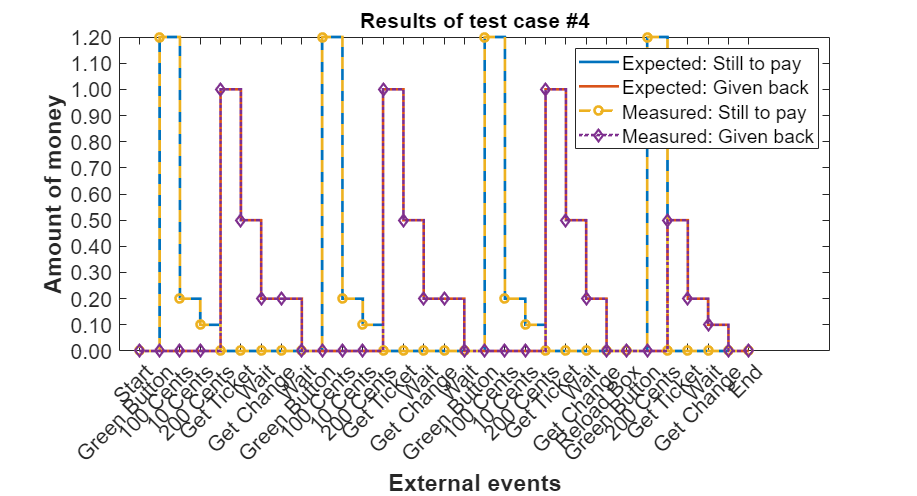


[Terse] Diagnostic logged (2022-07-01 17:30:32):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_759db311-3e32-4dcb-9e4b-fdcd799e8e18.fig
--> C:\Users\sebas\AppData\Local\Temp\c3fbc84f-1838-4fce-95d7-483d4a16b565\Figure_759db311-3e32-4dcb-9e4b-fdcd799e8e18.png
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.
    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.pdf
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tp216940f0_7f40_49a0_8cdb_34516455cf1e\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                            Name                            Passed    Failed    Incomplete    Duration      Details   
    ____________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_1_StraightTicketPurchase'       }    true      false       false        16.879     {1×1 struct}
    {'TestApp/testCase_2_CancelTicketPurchase'         }    true      false       false        31.641     {1×1 struct}
    {'TestApp/testCase_3_SameValueCoinTicketPurchase'  }    true      false       false        21.596     {1×1 struct}
    {'TestApp/testCase_4_BiggestChangeOnTicketPurchase'}    true      false       false        35.872     {1×1 struct}
    {'TestApp/testCase_4_FullyEmptyAndReloadCashBox'   }    true      false      